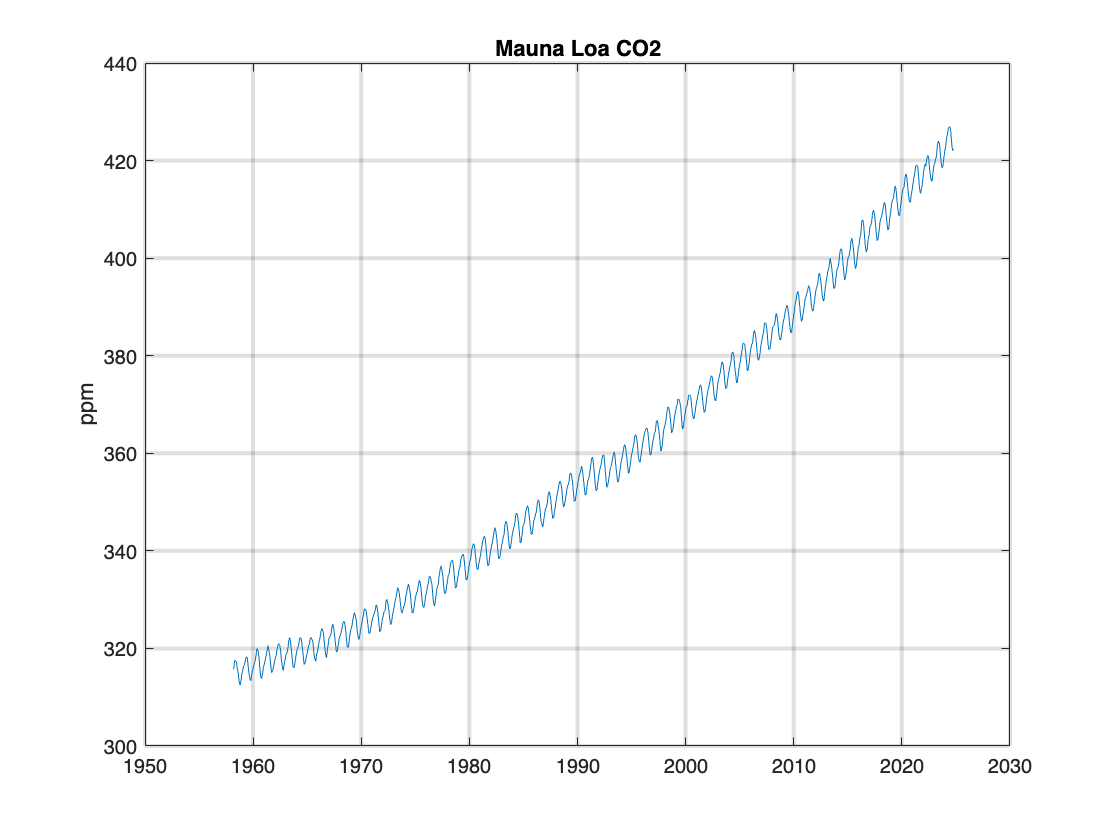


figure
[years, co2] = readHawaiiCO2('co2_mm_mlo.csv');
plot(years,co2)
title('Mauna Loa CO2');
ylabel('ppm');
grid on
ax = gca;                           % get current axis (plot area)
ax.GridLineWidth = 2.0;

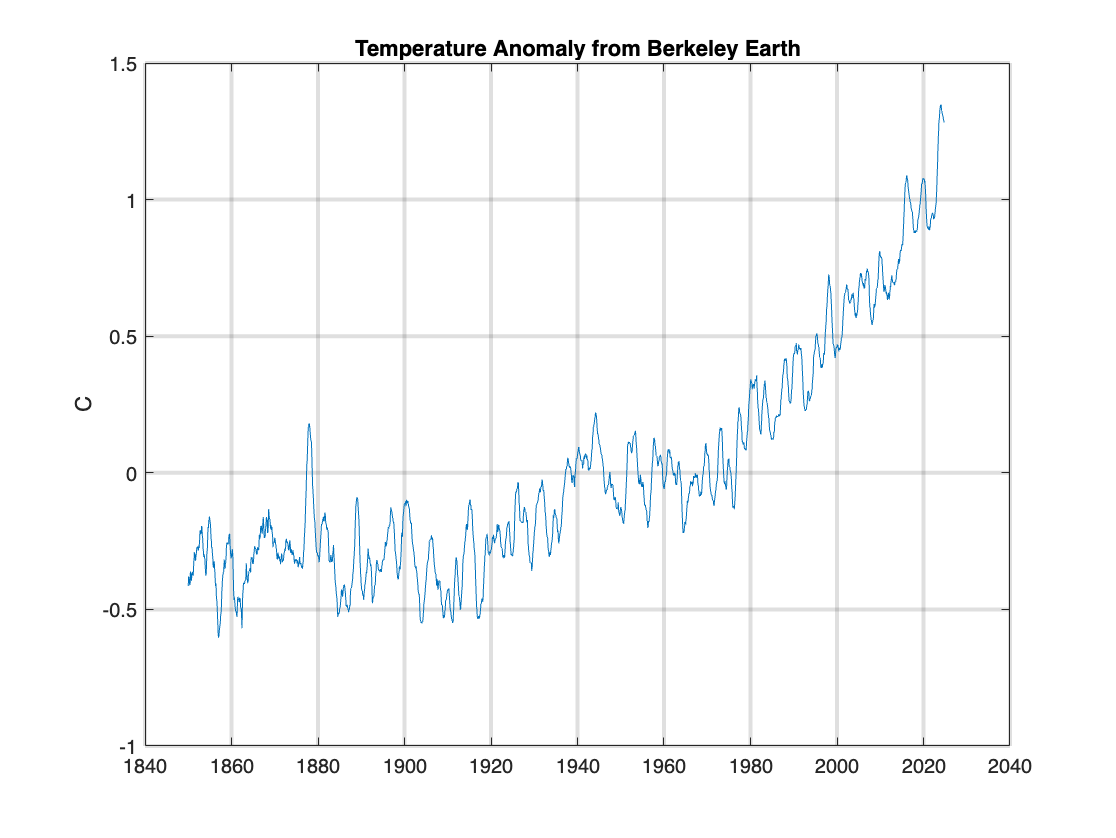



figure
[years ta] = readRecentTempAnomaly('Land_and_Ocean_complete.txt');
plot(years,movmean(ta,[5 6]));
title('Temperature Anomaly from Berkeley Earth')
ylabel('C');
grid on
ax = gca;
ax.GridLineWidth = 2.0;

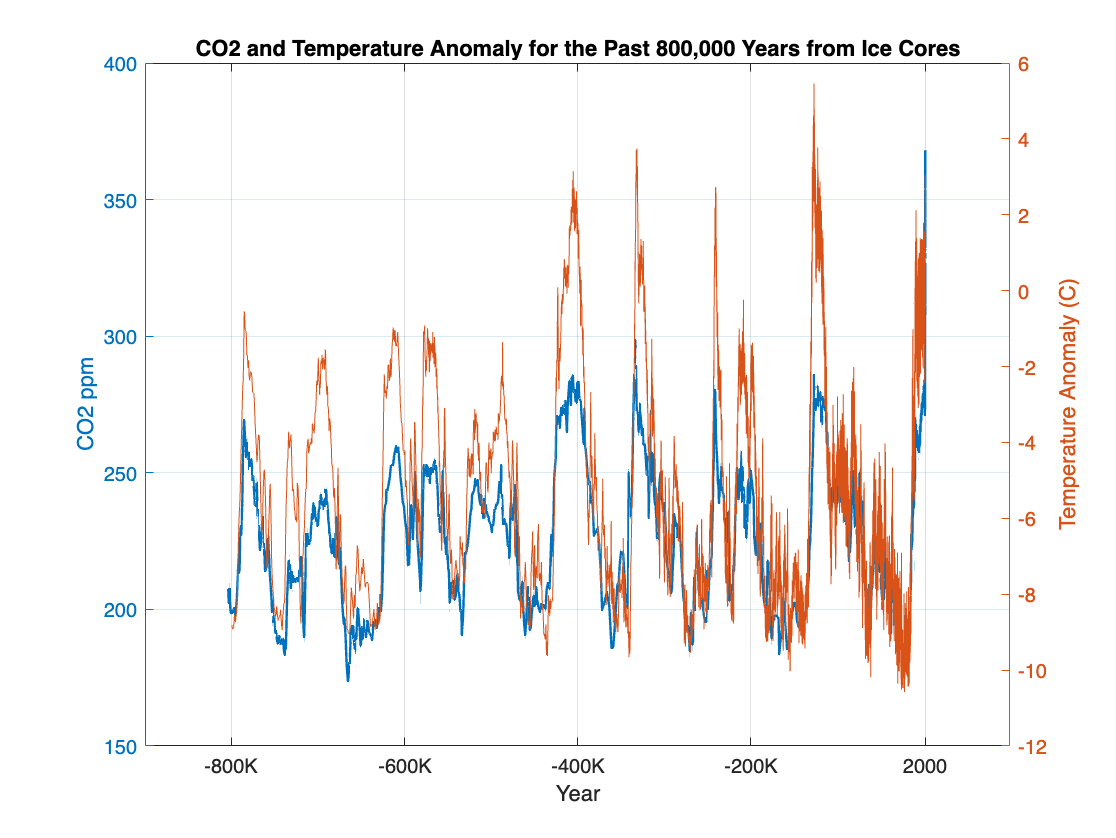


[age, co2] = readIcecoreCO2('antarctica2015co2composite.txt');
years = flip(1950 - age);   % years before 1950
co2 = flip(co2);

figure
yyaxis left;
plot(years,co2,'LineWidth',1.2);
grid on
title('CO2 and Temperature Anomaly for the Past 800,000 Years from Ice Cores');
ylabel('CO2 ppm');
xlabel('Year')

ax = gca;                           % get current axis (plot area)
ax.XRuler.Exponent = 0;             % How to get rid of annoying common exponent on axis

xticks([-800000:200000:-1 2000]);
xticklabels({'-800K', '-600K' '-400K' '-200K' '2000'});

[ageT, tAnom] = readIcecoreTempAnomaly('EPICA Dome C Ice Core 800KYr Deuter.txt');
yearsT = flip(1950 - ageT);   % years before 1950
tAnom = flip(tAnom);
yyaxis right;
plot(yearsT,tAnom);
ylabel('Temperature Anomaly (C)')

Helper functions:

function [years, co2] = readHawaiiCO2(filename)
    % Open the file for reading
    fid = fopen(filename, 'rt');
    if fid == -1
        error('Could not open file %s for reading.', filename);
    end

    % Initialize arrays to hold the data
    years = [];
    co2 = [];

    % Read the file line by line
    while ~feof(fid)
        % Get the current line
        line = strtrim(fgetl(fid)); % Trim whitespace around the line
        % Convert the line into numeric values
        numericValues = str2num(line); %#ok<ST2NM>
        if isempty(numericValues)
            continue;
        end
        % Append the values to the respective arrays
        if numel(numericValues) >= 8 % Ensure there are at least 3 columns
            years = [years; numericValues(3)];
            co2 = [co2; numericValues(4)];
        end
    end
    % Close the file
    fclose(fid);
end

function [years, tAnom] = readIcecoreTempAnomaly(filename)
    % Open the file for reading
    fid = fopen(filename, 'rt');
    if fid == -1
        error('Could not open file %s for reading.', filename);
    end

    % Initialize arrays to hold the data
    years = [];
    tAnom = [];

    % Read the file line by line
    while ~feof(fid)
        % Get the current line
        line = strtrim(fgetl(fid)); % Trim whitespace around the line
        % Check if the line starts with '%' or is empty
        if isempty(line) 
            continue; % Skip this line (it's metadata)
        end
        % Convert the line into numeric values
        numericValues = str2num(line); %#ok<ST2NM>
        if isempty(numericValues)
            continue;
        end
        % Append the values to the respective arrays
        if numel(numericValues) >= 5 % Ensure there are at least 3 columns
            years = [years; numericValues(3)];
            tAnom = [tAnom; numericValues(5)];
        end
    end
    % Close the file
    fclose(fid);
end

function [years, co2] = readIcecoreCO2(filename)
    % Open the file for reading
    fid = fopen(filename, 'rt');
    if fid == -1
        error('Could not open file %s for reading.', filename);
    end

    % Initialize arrays to hold the data
    years = [];
    co2 = [];

    % Read the file line by line
    while ~feof(fid)
        % Get the current line
        line = strtrim(fgetl(fid)); % Trim whitespace around the line
        % Check if the line starts with '%' or is empty
        if isempty(line) || line(1) == '#'
            continue; % Skip this line (it's metadata)
        end
        % Convert the line into numeric values
        numericValues = str2num(line); %#ok<ST2NM>
        if isempty(numericValues)
            continue;
        end
        % Append the values to the respective arrays
        if numel(numericValues) >= 2 % Ensure there are at least 3 columns
            years = [years; numericValues(1)];
            co2 = [co2; numericValues(2)];
        end
    end
    % Close the file
    fclose(fid);
end

function [years, tempAnomaly] = readRecentTempAnomaly(filename)
    % Open the file for reading
    fid = fopen(filename, 'rt');
    if fid == -1
        error('Could not open file %s for reading.', filename);
    end

    % Initialize arrays to hold the data
    years = [];
    months = [];
    tempAnomaly = [];

    % Read the file line by line
    while ~feof(fid)
        % Get the current line
        line = strtrim(fgetl(fid)); % Trim whitespace around the line
        % Check if the line starts with '%' or is empty
        if isempty(line) || line(1) == '%'
            continue; % Skip this line (it's metadata)
        end
        % Convert the line into numeric values
        numericValues = str2num(line); %#ok<ST2NM>
        % Append the values to the respective arrays
        if numel(numericValues) >= 3 % Ensure there are at least 3 columns
            years = [years; numericValues(1)];
            months = [months; numericValues(2)];
            tempAnomaly = [tempAnomaly; numericValues(3)];
        end
        if length(years) > 1 && years(end) < years(end-1)  % Manually added code
            years = years(1:end-1);
            months = months(1:end-1);
            tempAnomaly = tempAnomaly(1:end-1);
            break;
        end
    end
    years = years + (months-1)/12;  % Manualy added code
    % Close the file
    fclose(fid);
end